# Interactive signal safeguarding

## 信号の読み込みと確認

[fileN, pathN] = uigetfile('*.wav');
disp(fileN);

gnbWake44kOrg1p3s.wav


[xIn, fs] = audioread(string(pathN)+string(fileN));
infoStr = audioinfo(string(pathN)+string(fileN))

infoStr = フィールドをもつ struct :
             Filename: '/Users/kawahara/m-file/RAPHSODEE/gnbWake44kOrg1p3s.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 44100
         TotalSamples: 57330
             Duration: 1.3000
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 24


## 高速にFFTWできる長さに調整します

nData = ceil(length(xIn)/2^12)*2^12;
x = zeros(nData,1);
x(1:length(xIn)) = xIn;

## 全体を離散フーリエ変換します

xF = fft(x);
fx = (0:nData-1)'/nData*fs;
fxBi = fx;
fxBi(fxBi >fs/2) = fxBi(fxBi >fs/2)-fs;

## 周波数平滑化用のガウス関数を設計します（対数波数軸）

1/6オクターブ離れた位置でレベルが1/sqrt(2)になるように設定する

flxBi = log2(abs(fxBi));
flxBi(1) = flxBi(2);
%exp(-(1/6)^2/flb^2) = 1/sqrt(2);
%-(1/6)^2/flb^2 = log(1/sqrt(2));
%-(1/6)^2/flb^2 = -log(sqrt(2));
%(1/6)^2/flb^2 = log(sqrt(2));
%(1/6)/flb = sqrt(log(sqrt(2)));
%(1/6)/sqrt(log(sqrt(2))) = flb;
fc = 20*2.0 .^(0:1/24:log2(fs/2/20))';
flc = log2(fc);
nChannel = length(flc);
fBank = zeros(nData,nChannel);
avPw = zeros(nChannel,1);
for ii = 1:nChannel
    flb = (1/12)/sqrt(log(sqrt(2)));
    fBank(:,ii) = exp(-(flc(ii)-flxBi).^2/flb^2);
    avPw(ii) = sum(fBank(:,ii).*abs(xF).^2)/sum(fBank(:,ii));
end

## 操作用に表示します

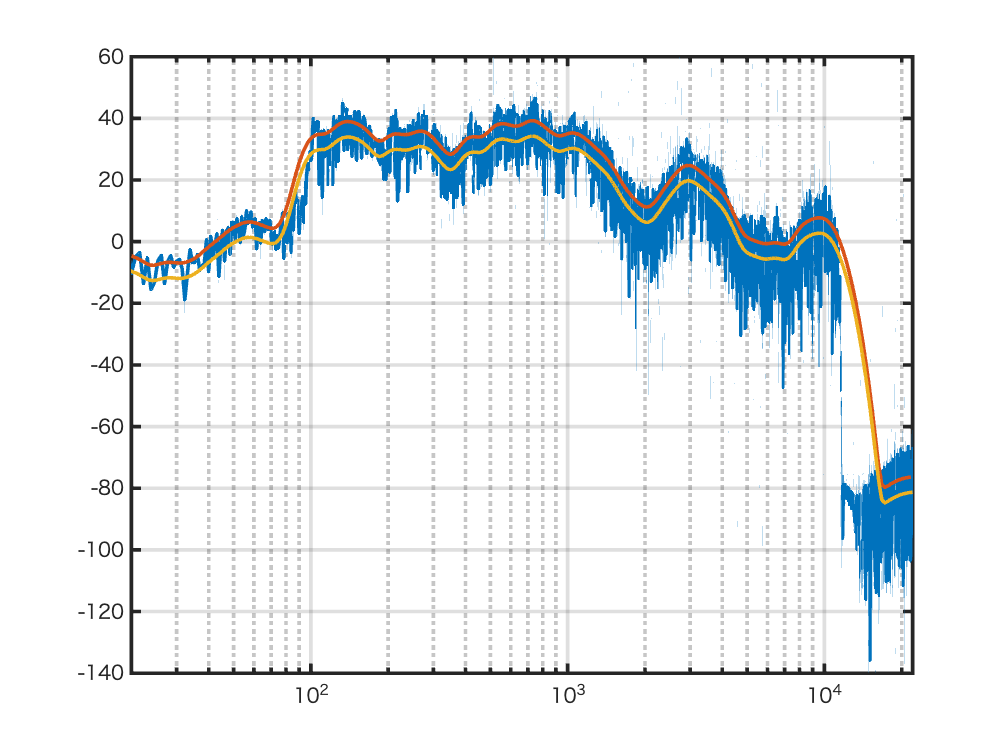

figure;
semilogx(fx, 20*log10(abs(xF)),"LineWidth",2);grid on;
set(gca,"xlim",[20 fs/2],"LineWidth",2);
hold on
semilogx(fc,10*log10(avPw),"LineWidth",2);
absFxBi = abs(fxBi);
avPwi = interp1(fc,10*log10(avPw),absFxBi,"linear","extrap");
gardHandle = semilogx(absFxBi, avPwi-5,"LineWidth",2);

## 保護のレベルを設定します

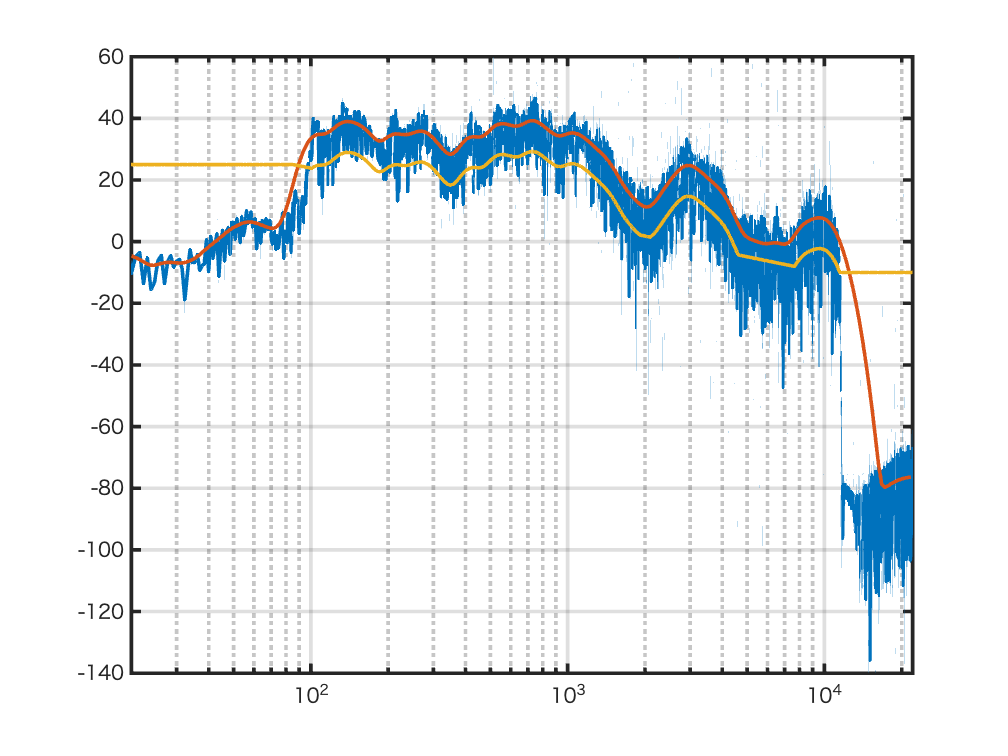

fLow = 85;
fHigh = 10000;
lowFloor = 25;
highFloor = 0; 
thLevel = -10;
guardShaper = flxBi*0;
guardShaper(absFxBi<=fLow) = lowFloor;
guardShaper(absFxBi>=fHigh) = highFloor;
flxBiSeg = flxBi(absFxBi>fLow & absFxBi <fHigh);
guardShaper(absFxBi>fLow & absFxBi <fHigh) =  lowFloor ...
    + (highFloor-lowFloor)/(max(flxBiSeg)-flxBiSeg(1))*(flxBiSeg-flxBiSeg(1));
guardShaper = max(guardShaper,avPwi+thLevel);
set(gardHandle,"YData",guardShaper)

## 信号を保護します

guardThreshold = 10.0 .^(guardShaper/20);
xFfix = xF;
xFfix(abs(xF)<guardThreshold) = guardThreshold(abs(xF)<guardThreshold) ...
    .* xFfix(abs(xF)<guardThreshold) ./abs(xFfix(abs(xF)<guardThreshold));
xSg = real(ifft(xFfix));

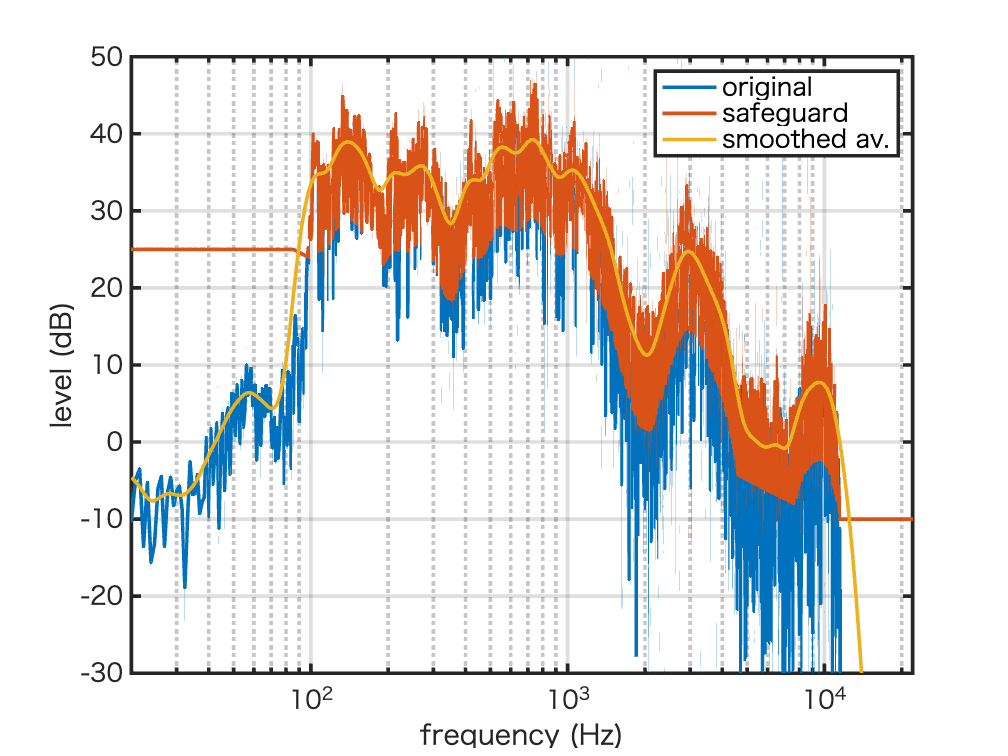

figure;
semilogx(fx, 20*log10(abs(xF)),"LineWidth",2);grid on;
set(gca,"xlim",[20 fs/2],"LineWidth",2,"fontsize",14);
hold all
semilogx(fx, 20*log10(abs(fft(xSg))),"LineWidth",2);grid on;
semilogx(fc,10*log10(avPw),"LineWidth",2);
axis([20 fs/2 -30 50])
legend("original","safeguard","smoothed av.","fontsize",14)
xlabel("frequency (Hz)")
ylabel("level (dB)")
fName = [fileN(1:end-4), 'sgspec.png'];
print("-dpng","-r200",fName)

fNameOrg = [fileN(1:end-4), 'Org.wav'];
fNameSg = [fileN(1:end-4), 'Sg.wav'];
audiowrite(fNameOrg,x/abs(max(x))*0.8,fs,"BitsPerSample",24);
audiowrite(fNameSg,xSg/abs(max(xSg))*0.8,fs,"BitsPerSample",24);